# Load data

clear
load('Assignment_Data_SC42145.mat');
G = tf(FWT(1:2,1:2));

% build Performance Weight matrices
Wp11 = tf([1/1.8, 0.8*pi], [1, 0.8*pi*1e-4]);
Wu22 = tf([5e-3, 7e-4, 5e-5], [1, 14e-4, 1e-6]);

Wp = [Wp11 0; 0 0.2];
Wu = [0.01 0; 0 Wu22];

% build Uncertainty Weight matrices
Wi1 = tf([1/(16*pi), 0.3], [1/(64*pi), 1]);
Wi2 = Wi1;
Wo1 = tf([0.05, 0.2], [0.01, 1]);
Wo2 = Wo1;

Wi = [Wi1 0; 0 Wi2];
Wo = [Wo1 0; 0 Wo2];

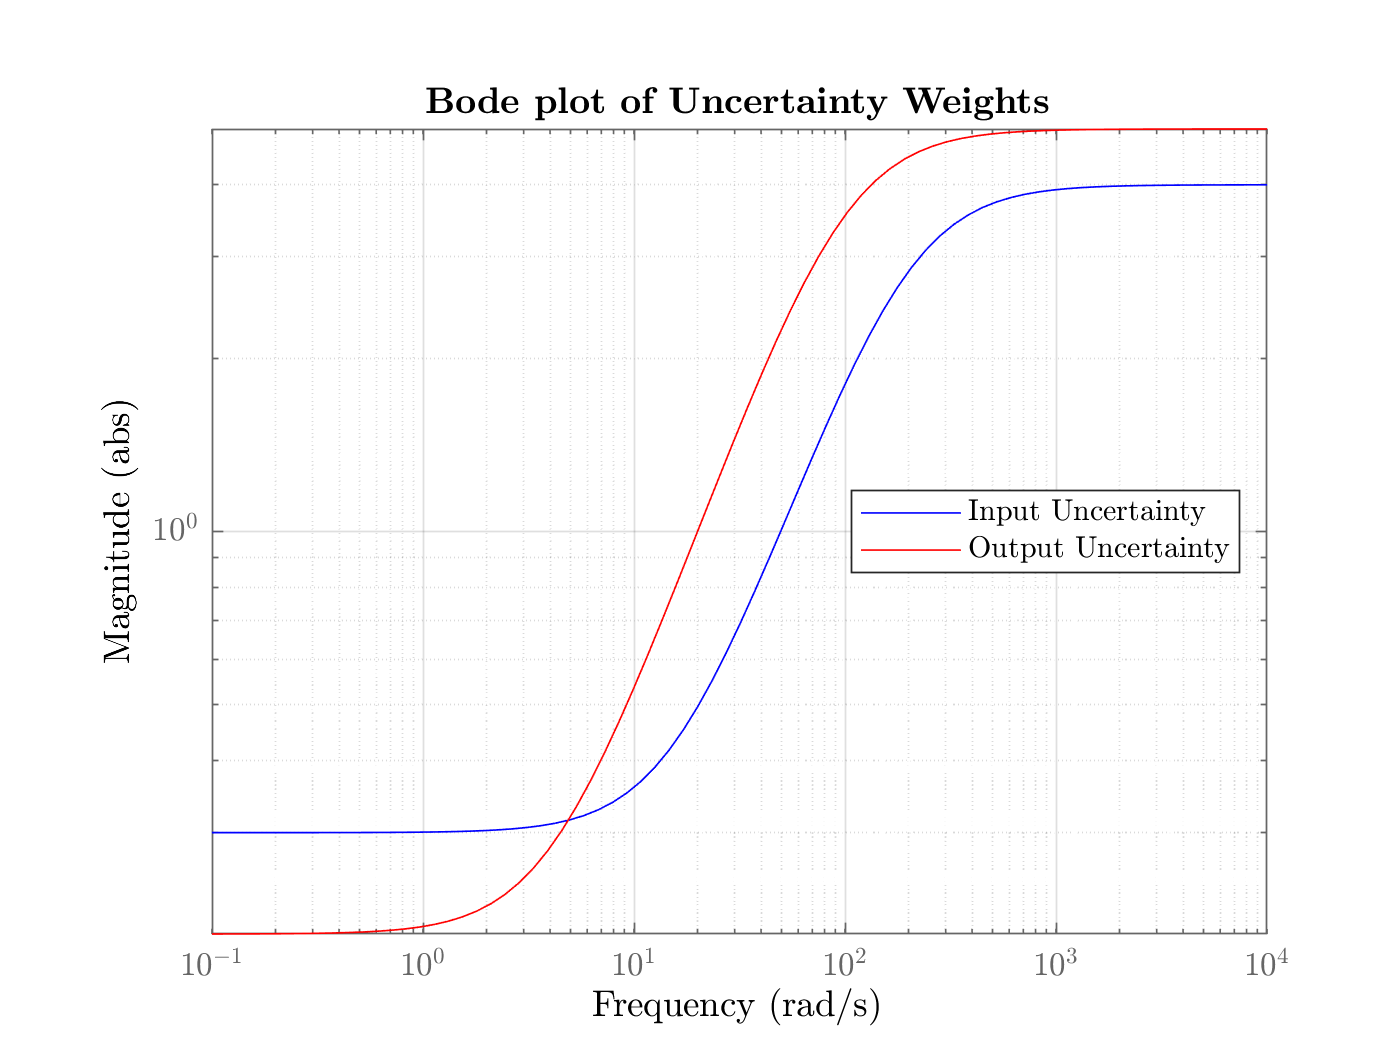

% plot weights
figure();
bodemag(Wi1, 'blue'); hold on;
latex_bodemag(Wo1, 'Uncertainty Weights', 'red');
legend('Input Uncertainty', 'Output Uncertainty', 'interpreter', 'latex', 'Location', 'east');
saveas(gcf, 'Figures/ch4_uncertainty_weights.eps',  'epsc')

## Generalized Plant

P11 = [zeros(2,4); Wo*G zeros(2,2)];
P12 = [zeros(2,2) Wi; zeros(2,2) Wo*G];
P21 = [Wp*G Wp; zeros(2, 4)];
P22 = [Wp Wp*G; zeros(2,2) Wu];
P31 = [-G -1*eye(2)];
P32 = [-1*eye(2) -G];
P = [P11 P12; P21 P22; P31 P32];

P =
 
  From input "Beta (deg)" to output...
   1:  0
 
   2:  0
 
       -0.003994 s^5 - 0.01614 s^4 - 0.04405 s^3 - 0.1732 s^2 - 0.0004305 s - 0.006916
   3:  -------------------------------------------------------------------------------
        0.01 s^6 + 1.006 s^5 + 0.7077 s^4 + 11.02 s^3 + 4.715 s^2 + 0.5439 s + 0.1827
 
              -0.002437 s^4 - 0.01149 s^3 - 0.01071 s^2 - 0.01759 s - 0.0104
   4:  -----------------------------------------------------------------------------
       0.01 s^6 + 1.006 s^5 + 0.7077 s^4 + 11.02 s^3 + 4.715 s^2 + 0.5439 s + 0.1827
 
        -0.04438 s^5 - 0.2026 s^4 - 0.4904 s^3 - 2.177 s^2 - 0.002893 s - 0.08691
   5:  ----------------------------------------------------------------------------
       s^6 + 0.5982 s^5 + 10.98 s^4 + 4.712 s^3 + 0.5433 s^2 + 0.1828 s + 4.591e-05
 
            -0.009748 s^3 - 0.006961 s^2 - 0.01499 s - 0.0104
   6:  ------------------------------------------------------------
       s^5 + 0.5979 s^4 + 10.98 s^3 + 4.

N = lft()
